% =========================================================================
% Section 1: Data Calculation (Unchanged)
% =========================================================================
% Parameter settings
tspan = [0 150]; % Time range

% Define ODE system (no nutrient decay)
ode = @(t, y) -0*y;

% Initial conditions
initial_conditions = 500;

% Solve using ode15s
[t, y] = ode15s(ode, tspan, initial_conditions);

% =========================================================================
% Section 2: Cell Journal Style Plotting (Modified)
% =========================================================================

% --- 1. Create figure window ---
% Specifications: 6 cm width, 6.5 cm height, pure white background
fig = figure('Units', 'centimeters', 'Position', [10, 10, 6, 6.5], 'Color', 'w');

% --- 2. Precise space allocation (normalized units) ---
% Total height: 6.5 cm
% Margins allocated for 10pt font padding:
pos_top    = [0.23, 0.80, 0.72, 0.15]; % [left, bottom, width, height]
pos_bottom = [0.23, 0.17, 0.72, 0.50];

% ==================== Plot Top Subplot ====================
ax1 = axes('Position', pos_top);

% Deep cyan-gray line (Cell journal style), LineWidth = 1.5 pt
plot(ax1, t, y, 'Color', "#5D878B", 'LineWidth', 1.5);

% Axis labels (Font size 10 pt, Arial)
ylabel(ax1, 'Nutrients', 'FontSize', 10, 'FontName', 'Arial');

% Axis limits and formatting
xlim(ax1, [0 150]);
ylim(ax1, [0 550]);
set(ax1, ...
    'FontSize', 10, ...
    'FontName', 'Arial', ...
    'Box', 'off', ...
    'TickDir', 'out', ...
    'LineWidth', 0.8, ...      % Axis line width
    'XColor', 'k', 'YColor', 'k', ...
    'XTickLabel', [], ...      % Hide X-tick labels for compact layout
    'TickLength', [0.03, 0.03]);

% =========================================================================
% Section 3: Intermediate Data Calculation
% =========================================================================
a = 1.1;
params.K_BN = 250;      
params.K_HN = 50;      
params.K_HM = 30;      
params.Y_B = 0.5;        
params.Y_HN = 0.5;     
params.Y_HM = 1;       
params.delta_N = 0;  
params.alpha = 5;
params.gamma = 0.1;
params.Ncrit = 20;     
params.h = 8;   
params.mu_B = 0.2; 
params.mu_H = 1;   
params.delta_A = 0.1;
params.K_BD = 1;
params.epsilon = 0.6;
params.kappa = 2;
params.Y_BD = 1;

N0 = 500; B0 = 1; M0 = 10; H0=5;
tspan = [0 150];
y0_co = [N0; B0; H0; M0; 0; 0];

% Solve co-culture ODE
[t_co, y_co] = ode45(@(t, y) B_H_model(t, y, params), tspan, y0_co);
tt = t_co;
B = y_co(:,2);

% Solve mono-culture ODE
params.mu_B = params.mu_B * a;
params.alpha = 0;
y0_mono = [N0; B0; H0; M0; 0; 0]; 
[t_mono, y_mono] = ode45(@(t, y) B_H_model(t, y, params), tspan, y0_mono);

% ==================== Plot Bottom Subplot ====================
ax2 = axes('Position', pos_bottom);

% Plot area graphs (LineWidth = 1 pt)
p1 = area(ax2, tt, B, 'LineStyle','-','LineWidth', 1, ...
    'FaceColor', '#E37A7F', 'FaceAlpha', 0.3, 'EdgeColor', '#E37A7F'); 
hold(ax2, 'on');
p2 = area(ax2, t_mono, y_mono(:,2), 'LineStyle','-', 'LineWidth', 1, ...
    'FaceColor', '#8BCEE8', 'FaceAlpha', 0.3, 'EdgeColor', '#8BCEE8');

xlim(ax2, [0 150]);

% Set axis labels (Font size 10 pt, Arial)
xlabel(ax2, 'Time', 'FontSize', 10, 'FontName', 'Arial');
ylabel(ax2, '{\itBacillus} Biomass', 'FontSize', 10, 'FontName', 'Arial');

% Legend formatting (No border, 10 pt Arial)
lgd = legend(ax2, 'Cult', 'Self'); 
set(lgd, 'FontSize', 10, 'FontName', 'Arial', 'Box', 'off', 'Location', 'southeast');

% Axis formatting for bottom subplot
set(ax2, ...
    'FontSize', 10, ...
    'FontName', 'Arial', ...
    'Box', 'off', ...
    'TickDir', 'out', ...
    'LineWidth', 0.8, ...
    'XColor', 'k', 'YColor', 'k', ...
    'TickLength', [0.02, 0.02]);

exportgraphics(fig, 'Panel_1_2.pdf', 'ContentType', 'vector');

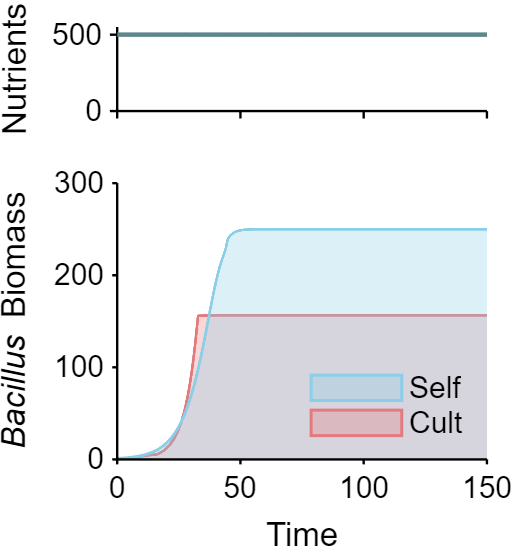

saveas(fig, 'Panel_1_2.emf');

function dydt = B_H_model(~, y, params)
    N = y(1); B = y(2); H = y(3); M = y(4); A = y(5); D = y(6);

    % Monod terms
    monod_B = N / (params.K_BN + N);
    monod_H_N = N / (params.K_HN + N);
    monod_H_M = M / (params.K_HM + M);
    monod_B_D = D / (params.K_BD + D);

    % Growth rates
    growth_B_N = params.mu_B * monod_B * B;
    growth_H = params.mu_H * monod_H_N * monod_H_M * H;
    growth_B_D = params.mu_B * monod_B_D * B;

    % Hill activation function
    hill_activate = (N^params.h) / (params.Ncrit^params.h + N^params.h);

    % Differential equations
    dNdt = - (1/params.Y_B)*growth_B_N - (1/params.Y_HN)*growth_H - params.delta_N*N;
    dBdt = growth_B_N + growth_B_D;
    dHdt = growth_H - params.kappa * A * H;
    dMdt = params.alpha * hill_activate * B - (1/params.Y_HM) * growth_H;
    dAdt = params.gamma * (1-hill_activate) * B  - params.delta_A * A;
    dDdt = params.epsilon * params.kappa * A * H - (1/params.Y_BD)*growth_B_D;

    dydt = [dNdt; dBdt; dHdt; dMdt; dAdt; dDdt];
end